# **Vision Artificial. GIEC - Sistemas de Vision Artificial. GIC**

# **Tema 3. Segmentación basada en bordes. Análisis global**

**  Departamento de Electrónica. Universidad de Alcalá.**

## **Análisis global**

### Transformada de Hough. Líneas rectas

Se pueden cerrar los contornos analizando la imagen global en busca de las rectas predominantes, círculos, elipses…

Ejecute el siguiente código (extraído de un ejemplo de Matlab) que utiliza la transformada de Hough para detectar segmentos en la imagen:

En este ejemplo se muestra cómo detectar líneas en una imagen mediante la transformada de H`ough.`

La transformada de Hough está diseñada para detectar líneas, utilizando la representación paramétrica de la recta:

`rho = x*cos(theta) + y*sin(theta)`

La variable (rho) es la distancia desde el origen a la línea a lo largo de un vector perpendicular y (theta) es el ángulo entre el eje x y este vector, tal y como se muestra en la figura 1. La función genera una matriz de espacio de parámetros cuyas filas y columnas corresponden a estos valores.

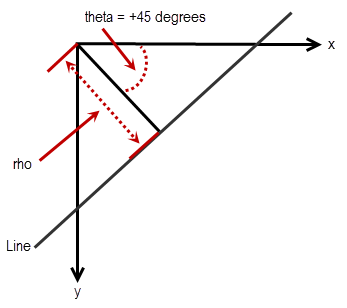

Figura 1.

close all;
clear all;
clc;

Lee una imagen en el espacio de trabajo y la convierte a escala de gris, si es necesario.

filename = 'circuit.tif'  
info = imfinfo(filename);
if strcmp(info.ColorType,'indexed')
    [X,map] = imread(filename);
    I = ind2gray(X,map);
elseif strcmp(info.ColorType,'truecolor')
    rgb=imread(filename);
    I=rgb2gray(rgb);
else
    I=imread(filename);
end

rotI = imrotate(I,33,'crop');

imshow(rotI)
title('Imagen original');

BW = edge(rotI,'canny');
imshow(BW);
title('Imagen de bordes');

Calcula la transformada de Hough de la imagen binaria devuelta por `edge`.

angles = [(-90:0.5:89)];

[H, theta, rho] = hough(BW,'Theta',angles);

Muestra la transformación, devuelta por la función `hough`.

figure
imshow(imadjust(rescale(H)),'XData',theta,'YData',rho,'InitialMagnification','fit');
title('Hough Transform array'); xlabel('\theta (degrees)'); ylabel('\rho (pixels)'); 
axis on, axis normal; colormap(gca,hot); colorbar

Después de calcular la transformación Hough, puede utilizar la función `houghpeaks` para buscar valores máximos en el espacio de parámetros. Estos picos representan líneas potenciales en la imagen de entrada.

Encuenta los picos en la matriz de transformación Hough.

th = ceil(0.85*max(H(:))); % umbral de búsqueda
max_peaks = 20; % número máximo de picos a encontrar

P = houghpeaks(H, max_peaks, 'threshold', th, 'Theta', angles)

Marque en la imagen H de la transformada los picos P obtenidos.

x = theta(P(:,2)); 
y = rho(P(:,1)); 
hold on;
plot(x,y,'*','color','blue');
hold off;

Después de identificar los picos de la transformada de Hough, puede utilizar la función `houghlines` para encontrar los puntos finales de los segmentos de línea correspondientes a los picos de la transformada de Hough. Esta función rellena automáticamente pequeños huecos en los segmentos de línea.

Buscar líneas en la imagen utilizando la función houghlines

lines = houghlines(BW, theta, rho, P, 'FillGap', 20, 'MinLength',50);

Cree un trazado que muestre la imagen original con las líneas superpuestas.

figure, 
imshow(rotI), 
hold on 

max_len=0;

for k = 1:length(lines)    
    
    xy = [lines(k).point1; lines(k).point2];    
    
    % dibuja las rectas
    plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');     
    
    % marca con una cruz el inicio y final de las rectas
    plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');    
    plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');     
  

end 
hold on

Si tiene dudas, mire la ayuda en las funciones *hough, houghpeaks y houghlines *de Matlab, que “grosso modo” calculan la Transformada de Hough (obteniendo la tabla de incidencias de acumuladores de módulo *P* y ángulo θ), obtienen los picos o máximos en la misma (con determinadas restricciones), y detectan líneas (uniendo segmentos) con unas determinadas especificaciones, respectivamente.

 Observe qué ocurriría si en vez de poner que se detecten cinco picos en la tabla de incidencias de acumuladores pone que se encuentre más picos (o un número alto, 1000 por ejemplo, para que se encuentren todos los picos mayores del umbral), o varía el umbral, ceil(0.3*max(H(:))), para detectar el pico: 

             P  = houghpeaks(H,1000,'threshold',ceil(0.3*max(H(:))));

 Compruebe asimismo qué pasaría si varía el número de píxeles no unidos entre segmentos pertenecientes a la misma recta que se unen (formando un único segmento en lugar de dos), y si varía la longitud mínima del segmento para considerarse como tal; es decir varíe los valores 5 y 20 de 'FillGap', y 'MinLength', respectivamente, en:

             lines = houghlines(BW,T,R,P,'FillGap',5,'MinLength',20);

## **Análisis global**

### Transformada de Hough. Circunferencias

close all;
clear all;
clc;

Lea la imagen en el espacio de trabajo y múestrela.

I = imread('circlesBrightDark.png'); 
imshow(I)

Defina el rango de radios.

Rmin = 30; 
Rmax = 65;

Encuentre todos los círculos claros en la imagen dentro del rango de radio usando la función `imfindcircles` .

[centersBright, radiiBright] = imfindcircles(I,[Rmin Rmax],'ObjectPolarity','bright');

Dibuja líneas azules alrededor de los bordes de los círculos claros.

viscircles(centersBright, radiiBright,'Color','b');

**Encuentre todos los círculos oscuros en la imagen y dibújelos.**